# Lead Controller Design and Experiment

Calculate the gain, poles, and zeros of the controller

% DC Motor Parameters
a = 3.6345;
b = 68.5131;

% Design Requirements
req_Ts = 4 / (0.9*a)

req_Ts = 1.2228

req_OS = 16;

% Calculate Design Point s_d
sigma = 4/req_Ts;
zeta = - log(req_OS/100) / sqrt(pi^2 + log(req_OS/100)^2);
w_n = sigma/zeta;
w = w_n*sqrt(1-zeta^2);
s_d = -sigma + w*1i

s_d = -3.2710 + 5.6076i


% Evaluate Plant TF at s_d
G_p = zpk([], [-a 0], b)

G_p =
 
    68.513
  -----------
  s (s+3.635)
 
Continuous-time zero/pole/gain model.
Model Properties


G_p_sd = evalfr(G_p, s_d);

% Calculate z_PD
phi_ULG = angle(G_p_sd);
phi_PD = -pi - phi_ULG;
z_PD = sigma + w/tan(phi_PD)

z_PD = 14.4946


% Calculate z_c
z_c = 0.7*z_PD

z_c = 10.1462


% Calculate p_c
phi_z = angle(s_d + z_c);
phi_c = phi_PD;
phi_p = phi_z - phi_c;
p_c = sigma + w/tan(phi_p)

p_c = 28.2478


% Evaluate Lead Controller TF at s_d
G_c = zpk(-z_c, -p_c, 1)

G_c =
 
  (s+10.15)
  ---------
  (s+28.25)
 
Continuous-time zero/pole/gain model.
Model Properties


G_c_sd = evalfr(G_c, s_d);

% Evaluate Gain K
K = abs(1/(G_c_sd*G_p_sd))

K = 1.5363

Graph the Root Locus

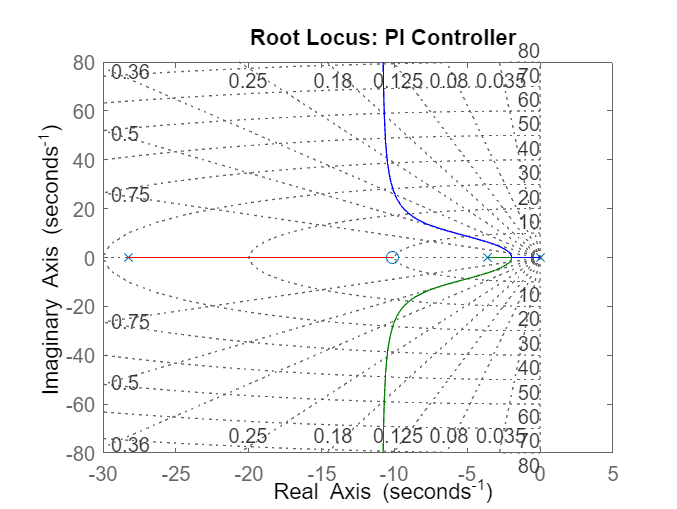

H = zpk([], [], 1); % define the sensor TF
OLTF = G_c*G_p*H; % blocks in cascade

% generate the RL for positive K
rlocus(OLTF); 
title("Root Locus: PI Controller")
sgrid; 

Calculate the Discrete-Time Transfer Function using Tustin's Approximation

Tsamp = 0.01; %s
G_c_z = c2d(G_c,Tsamp,'tustin')

G_c_z =
 
  0.92069 (z-0.9034)
  ------------------
      (z-0.7525)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.
Model Properties


Simulate the response

r = pi; % rad

% run the simulation
out = sim('Lead_Controller_Discrete', 2);

Evaluate the response

F_v = mean(out.Y.Data(end-10:end)) % calculate final value

F_v = 3.1414


t = out.Y.Time(out.Y.Data <= 0.98*F_v); % calculate times above -2% final value
% t = out.Y.Time(out.Y.Data >= 1.02*F_v); % calculate times above -2% final value

T_s_sim = t(end)

T_s_sim = 1.2100


u0 = out.u.Data(1) % initial input voltage

u0 = 4.4436


SSE = r - F_v % calculate steady state error

SSE = 2.2342e-04


OS_sim = (findpeaks(out.Y.Data) - F_v) / F_v

OS_sim =     0.2150
    0.0064



peak_input = findpeaks(out.u.Data)

peak_input = 0.0809

Plot the simulated response

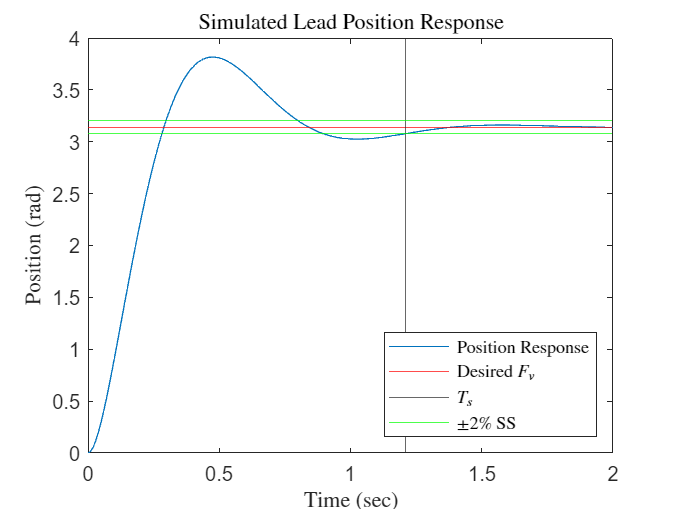

% plot position response
plot(out.Y.Time, out.Y.Data)
yline(r, 'r')
xline(T_s_sim)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
title("Simulated Lead Position Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Position (rad)", 'Interpreter','latex')
legend({"Position Response", "Desired $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

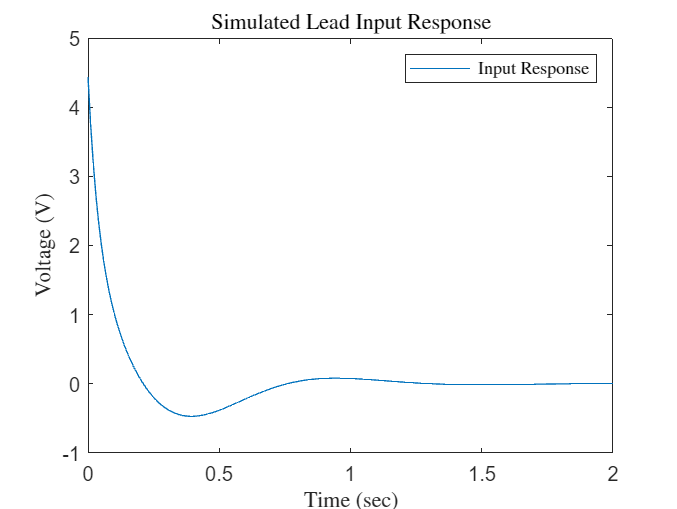


% plot input response
plot(out.u.Time, out.u.Data)
title("Simulated Lead Input Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Voltage (V)", 'Interpreter','latex')
legend('Input Response','Interpreter','latex', 'Location','northeast') 

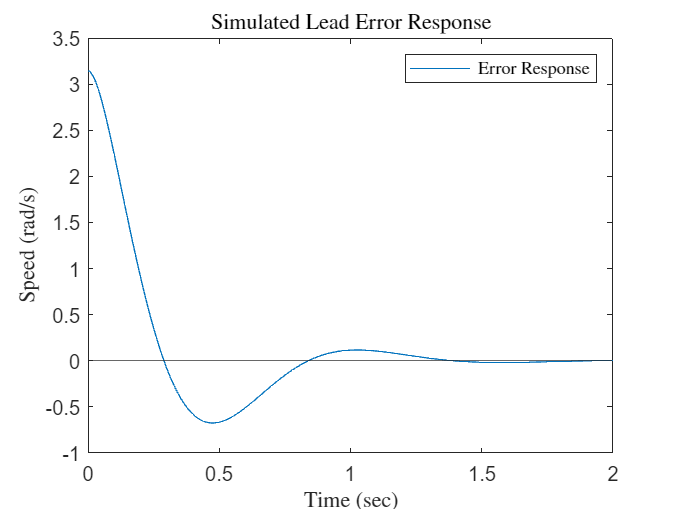


% plot error response
plot(out.e.Time, out.e.Data)
yline(0)
title("Simulated Lead Error Response", 'Interpreter','latex')
xlabel("Time (sec)", 'Interpreter','latex')
ylabel("Speed (rad/s)", 'Interpreter','latex')
legend('Error Response','Interpreter','latex', 'Location','northeast') 

Open serial port.

clear s % closes ports already open
s = serialport('COM11',9600) % Check COM#

Read serial port values and parse data into lists. 

values = 200;
t = zeros(1, values);
pos = zeros(1, values);
spd = zeros(1, values);
inpt = zeros(1, values);
error = zeros(1, values);

% loop through all 
for n = 1:values
    msg = s.readline();
    items = split(msg, ',');
    vals = arrayfun(@str2num, items);
    t(n) = vals(1);
    pos(n) = vals(2);
    spd(n) = vals(3);
    inpt(n) = vals(4);
    error(n) = vals(5);
end

% save lab8b3_11192024.mat t pos spd inpt error

Average results

% % load data from all three trials
% trial1 = load('lab8b1_11192024.mat');
% [B,I] = sort(trial1.t); % sort in correct order
% time1 = B;
% position1 = trial1.pos(I);
% input1 = trial1.inpt(I);
% error1 = trial1.error(I);
% 
% trial2 = load('lab8b2_11192024.mat');
% [B,I] = sort(trial2.t); % sort in correct order
% time2 = B;
% position2 = trial2.pos(I);
% input2 = trial2.inpt(I);
% error2 = trial2.error(I);
% 
% trial3 = load('lab8b3_11192024.mat');
% [B,I] = sort(trial3.t); % sort in correct order
% time3 = B;
% position3 = trial3.pos(I);
% input3 = trial3.inpt(I);
% error3 = trial3.error(I);
% 
% % calculate mean values
% time = (time1 + time2 + time3) / 3;
% position = (position1 + position2 + position3) / 3;
% input = (input1 + input2 + input3) / 3;
% error = (error1 + error2 + error3) / 3;

% TEST TRIAL
time = t;
position = pos; 
input = inpt;

Evaluate the response

F_v = mean(speed(150:end)) % steady state speed
i = find(speed >= 1.02 * F_v);
T_s = time(i(end-2))
OS = (max(speed)-F_v)/F_v

Plot speed, angle and input voltage with respect to time. 

% plot position
plot(time, position, '.')
yline(45, 'r')
xline(T_s)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
title("Experimental PI Position Response")
xlabel("Time (sec)")
ylabel("Position (rad)")
legend({"Position Response", "Desired $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

% plot input voltage
plot(time,input, '.')
title("Experimental PI Input Response")
xlabel("Time (s)")
ylabel("Voltage (V)")
legend("Input Response", 'Interpreter','latex', 'Location','southeast') 

% plot error response
plot(time, error, '.')
yline(0)
title("Experimental PI Error Response")
xlabel("Time (sec)")
ylabel("Speed (rad/s)")
legend("Erorr Response", 'Interpreter','latex', 'Location','southeast') 

Plot both simulated and experimental position, angle and input voltage with respect to time.

% plot position
plot(time, position, '.')
hold on 
plot(out.Y.Time, out.Y.Data)
yline(45, 'm')
xline(T_s)
% xline(T_s_sim)
yline(F_v * 0.98, 'g')
yline(F_v * 1.02, 'g')
hold off
title("PI Position Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('y (rad)', 'Interpreter','latex')
legend({"Experimental Response", "Simulated Response", "Desired $F_v$", '$T_s$', '$\pm{2\%}$ SS'},'Interpreter','latex', 'Location','southeast') 

% plot input voltage
plot(time, input, '.')
hold on 
plot(out.u.Time, out.u.Data)
hold off
title("PI Input Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('u (V)','Interpreter','latex')
legend({"Experimental Response", "Simulated Response"},'Interpreter','latex', 'Location','northeast') 

% plot error response
plot(time, error, '.')
hold on
plot(out.e.Time, out.e.Data)
yline(0)
hold off
title("PI Error Response", 'Interpreter','latex')
xlabel('t (s)', 'Interpreter','latex')
ylabel('e (rad/s)', 'Interpreter','latex')
legend({"Experimental Response", "Simulated Response", "SS"},'Interpreter','latex', 'Location','northeast') 